# Create a Bat-Mesh using the visual-hull method

Import all the camera data, and set up the camera matrix

%set up the values for the camera matrix
f = [720,0,360;0,654.5455,243;0,0,1];

%the camera resolutions
camRes = [720;486];

%the camera names
camNames = ["cam1","cam2","cam19","cam20","cam29","cam30","cam39","cam40","cam49","cam50"];

%the x and y positions of each of the cameras, in order
camX = [-3.9497,-3.949,13.945,13.945,-9.901,-9.901,20.024,20.024,3.9215,3.9215];
camY = [-0.058516,10.065,10.065,-0.0585,10.065,-0.0585,10.065,-0.0585,10.065,-0.0585];
camZ = [-12.732,-12.732,-12.801,-12.801,2.1774,2.1774,2.172,2.1728,14.009,14.009];

%the theta rotations of each camera, in order, in degrees
theta1 = [149,213,215,152,117,108,374,316,214,150];
theta2 = [38.1,39.9,-36.7,-38.5,88.5,87.8,-85.8,-84,180,178];
theta3 = [-1.9,-1.9,-1.82,-1.91,-97.1,-42.1,-160,-165,1.46,1.5];

%the focal lengths (50mm)
cameraFocs = 50*(1/1000)*ones(size(camNames));

%the half sensor sizes
horizSenseSize = 50;
vertSenseSize = camRes(2)*(horizSenseSize/camRes(1));
halfSenses = 0.5*vertSenseSize*ones(size(camNames));

%thecamera fovs (angle in x and y)
camFovs = 180-2*atand(halfSenses./cameraFocs).*ones(size(camNames));

%the final camera matrix
cameraMatrix = struct('camname',camNames,'xpos',camX,'ypos',camY,'zpos',camZ,'theta1',theta1,'theta2',theta2,'theta3',theta3,'foc',cameraFocs,'halfsense',halfSenses,'fov',camFovs);

%set up the videos to import
dataDirectory = uigetdir('C:\Users\yohan\Documents\Research\PHD - Muller\Bat Kinematics\Bat Visual Hull\Video Data Initial Anim');
directoryInfo = dir(dataDirectory);

%set up the bat positions at certain frames for reference purposes
batPosAtFrame = [57,-2.18, 1.824, 0;
                 192, 3.6929, 10.756, 4.5903;
                 279, 3.2948, 18.901, 3.9875];

%import the bat mesh at a few points just so that we can plot and test it
dataDirectoryMesh = uigetdir('C:\Users\yohan\Documents\Research\PHD - Muller\Bat Kinematics\Bat Visual Hull\Mesh Data Frames');
directoryInfoMesh = dir(dataDirectoryMesh);

%set the new camera matricies here
camCombinedMat = zeros([10 3 4]);
camCombinedMat(1,:,:) = [763.193115234375 159.17526245117188 -200.49801635742188 470.9560546875; -55.21266174316406 688.8462524414062 -99.60523986816406 -1445.92333984375; 0.5462493896484375 0.4943245053291321 0.6762062907218933 10.795791625976562];
camCombinedMat(2,:,:) = [739.5904541015625 -219.6693115234375 -229.6766357421875 2207.850341796875; 372.13702392578125 406.4581298828125 428.7009582519531 2837.05615234375; 0.5209146738052368 -0.5592580437660217 0.6448862552642822 15.89686393737793];
camCombinedMat(3,:,:) = [395.064697265625 -219.66946411132812 666.0849609375 5228.5234375; -330.6201171875 406.45819091796875 461.47686767578125 6427.1611328125; -0.5063703656196594 -0.5592581033706665 0.6563684344291687 21.092647552490234];
camCombinedMat(4,:,:) = [372.1611328125 159.17514038085938 695.8158569335938 3726.8984375; 84.07026672363281 688.8466186523438 -76.82325744628906 -2115.505859375; -0.5309547185897827 0.4943245053291321 0.6882813572883606 16.244110107421875];
camCombinedMat(5,:,:) = [296.1358337402344 -219.66885375976562 -715.5761108398438 6701.06884765625; 567.5582275390625 406.45916748046875 -12.146903038024902 1554.8873291015625; 0.8289129734039307 -0.5592568516731262 0.011630085296928883 13.810522079467773];
camCombinedMat(6,:,:) = [333.6619873046875 159.17518615722656 -715.0755004882812 4869.9111328125; -111.89154052734375 688.8463134765625 -21.20995330810547 -1021.34326171875; 0.8691924810409546 0.4943241477012634 0.012167436070740223 8.608269691467285];
camCombinedMat(7,:,:) = [-346.63818359375 -219.66957092285156 692.5226440429688 7647.43505859375; -566.9708251953125 406.458251953125 -28.54368019104004 7324.369140625; -0.8259490728378296 -0.5592582821846008 -0.07098285108804703 22.322227478027344];
camCombinedMat(8,:,:) = [-384.0320129394531 159.17514038085938 689.3349609375 6201.53369140625; 110.08491516113281 688.84619140625 29.1715145111084 -2227.466796875; -0.8660873174667358 0.49432462453842163 -0.07440418750047684 17.53350257873535];
camCombinedMat(9,:,:) = [-713.6340942382812 -219.66940307617188 -300.7858581542969 9223.109375; -8.453370094299316 406.45843505859375 -567.6258544921875 3893.986328125; 0.017023922875523567 -0.5592581033706665 -0.8288187980651855 17.172828674316406];
camCombinedMat(10,:,:) = [-712.8892822265625 159.17527770996094 -338.3082275390625 7544.2158203125; -21.937763214111328 688.846435546875 111.75160217285156 -1439.17138671875; 0.017823435366153717 0.4943247139453888 -0.8690946102142334 12.13400650024414];

%or simply take the matricies from blender and HOPE they work
%the list of camera matricies
% cam1Mat = [0.7869, -0.0261, -0.6166, -4.7438;
%             -0.2871,  0.8689, -0.4032, -6.2170;
%             0.5462,  0.4943,  0.6762, 10.7958];
% 
% cam2Mat = [0.7668, -0.0255, -0.6414, -4.8820;
%             0.3752,  0.8286,  0.4155, -1.5673;
%             0.5209, -0.5593,  0.6449, 15.8969];
% 
% cam19Mat = [0.8019, -0.0255, 0.5969, -3.2845;
%             -0.3171,  0.8286, 0.4614,  1.9886;
%             -0.5064, -0.5593, 0.6564, 21.0926];
% 
% cam20Mat = [0.7824, -0.0261,  0.6223, -2.9458;
%             0.3256,  0.8689, -0.3729, -9.2626;
%             -0.5310,  0.4943,  0.6883, 16.2441];
% 
% cam29Mat = [-0.0032, -0.0255, -0.9997,  2.4018;
%              0.5594,  0.8286, -0.0229, -2.7516;
%              0.8289, -0.5593,  0.0116, 13.8105];
% 
% cam30Mat = [0.0288, -0.0261, -0.9992,  2.4596;
%             -0.4936,  0.8689, -0.0369, -4.7562;
%              0.8692,  0.4943,  0.0122,  8.6083];
% 
% cam39Mat = [-0.0685, -0.0255,  0.9973, -0.5397;
%             -0.5596,  0.8286, -0.0173,  2.9029;
%             -0.8259, -0.5593, -0.0710, 22.3222];
% 
% cam40Mat = [-0.1003, -0.0261,  0.9946, -0.1535;
%             0.4897,  0.8689,  0.0722, -9.9124;
%             -0.8661,  0.4943, -0.0744, 17.5335];
% 
% cam49Mat = [-0.9997, -0.0255, -0.0033,  4.2235;
%             -0.0192,  0.8286, -0.5595, -0.4263;
%              0.0170, -0.5593, -0.8288, 17.1728];
% 
% cam50Mat = [-0.9990, -0.0261, -0.0353,  4.4111;
%             -0.0401,  0.8689,  0.4934, -6.7035;
%              0.0178,  0.4943, -0.8691, 12.1340];
% 
% %combine these matricies
% camCombinedMat = zeros([10 3 4]);
% camCombinedMat(1,:,:) = cam1Mat;
% camCombinedMat(2,:,:) = cam2Mat;
% camCombinedMat(3,:,:) = cam19Mat;
% camCombinedMat(4,:,:) = cam20Mat;
% camCombinedMat(5,:,:) = cam29Mat;
% camCombinedMat(6,:,:) = cam30Mat;
% camCombinedMat(7,:,:) = cam39Mat;
% camCombinedMat(8,:,:) = cam40Mat;
% camCombinedMat(9,:,:) = cam49Mat;
% camCombinedMat(10,:,:) = cam50Mat;
% 
% %forget this 
% %pre-compute the P matrix (the needed transformation matrix)
% %P = f*camCombinedMat;

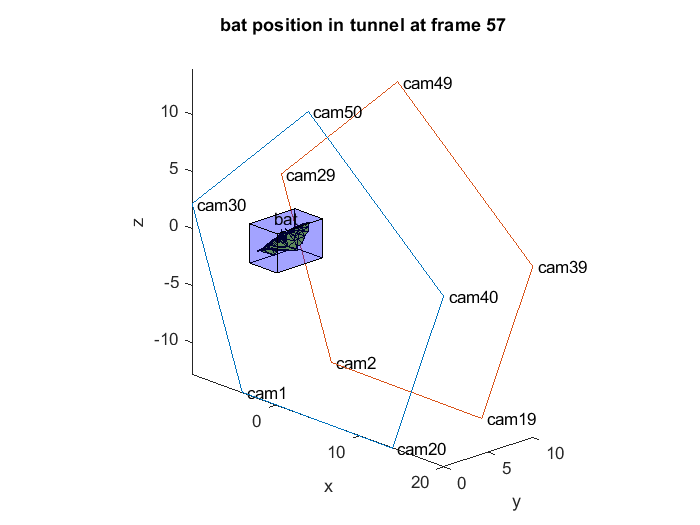

%plot the camera positions with the bat position for a few frames
figure(1)
clf
hold on
%scatter3(camX,camY,camZ,'r*');
for i = 1:length(camNames)
    text(camX(i),camY(i),camZ(i)," "+camNames(i));
end


%plot cameras 1, 30 50 40 and 20 to get the pentagon for the first few
%cameras
plot3(camX([1,6,10,8,4,1]),camY([1,6,10,8,4,1]),camZ([1,6,10,8,4,1]));
plot3(camX([9,5,2,3,7,9]),camY([9,5,2,3,7,9]),camZ([9,5,2,3,7,9]));
%scatter3(batPosAtFrame(1,2),batPosAtFrame(1,3),batPosAtFrame(1,4),'g*')
text(batPosAtFrame(1,2),batPosAtFrame(1,3),batPosAtFrame(1,4) + 2.5,"bat")

%load the STL data
singleObjData = readObj(fullfile(directoryInfoMesh(3).folder,directoryInfoMesh(3).name));

%display the obj file
objVerticiesRedone = [singleObjData.v(:,1),-1*singleObjData.v(:,3),singleObjData.v(:,2)];
patch('Faces',singleObjData.f.v,'Vertices',objVerticiesRedone,'FaceColor',[0.4660 0.6740 0.1880])

%also plot the bat using the mesh here
xlabel('x')
ylabel('y')
zlabel('z')
title("bat position in tunnel at frame 57")
%plot the cube region where we will generate the visual hull inside

%get the bottom left corner of the bat, and the top right corner of the bat
%the bottom left is the origin and the top right defines the edge size
%add the edge lengths plus a small amount to create the size of box we want

bottLeftCorner = min(objVerticiesRedone);
topRightCorner = max(objVerticiesRedone);

%add a buffer of 0.2
edgeLengths = topRightCorner - bottLeftCorner + 0.2;

%set the actual bottom left
bottLeftCorner = bottLeftCorner - [0.1 0.1 0.1];

%now plot the box
plotcube(edgeLengths,bottLeftCorner,0.2,[0 0 1]);
axis equal

view([46.4 20.5])

Find the frames which have bats in them save this for each timestep to reduce the computation of the rays

%for each camera for each frame, keep track of which frame numbers we need
%to cast rays for. Make sure to save the frames, and frame numbers here

%load a test video(note, they should all have the same number of frames)
%so getting the frames for this should be getting the frame lengths for all
dataFile = fullfile(dataDirectory,camNames(1) +".avi");
v = VideoReader(dataFile);

%get the matrix to store the frames, the dimensions are the number of
%frames, the width of the frame and the height of the frame
%storedFrames = zeros([v.NumFrames length(camNames) v.Width v.Height]);

%store an extra information matrix to see if the camera at a certain frame
%has detected a bat
batStoredFrame = zeros([v.NumFrames length(camNames)]);
batInsideFrame = zeros([v.NumFrames length(camNames)]);

%create the struct to store the camera frames
%one row for each camera, each column contains a timestep, then all the
%frame data
for i = 1:length(camNames)
    %for each camera, load the corrosponding video
    camVid = VideoReader(fullfile(dataDirectory,camNames(i) + ".avi"));
    
    %get the number of frames
    frameNumber = camVid.NumFrames;
    
    %for each frame, threshold it, then do blob detection, if a blob is
    %detected, save the frame
    for f = 1:frameNumber
        
        %get the threshold image
        greyImg = rgb2gray(read(camVid,f));
        threshImg = imbinarize(greyImg,0.6);
        
        %count all the white pixels in this image, if they are over some
        %number, then we have a bat and we need to save this frame
        numWhitePix = sum(sum(threshImg));
        
        numToLook = 2;
        
        %if these are both one then we're ok to save the frame
        bottomTopContainsBat = min(min(threshImg(1:numToLook,:)))*min(min(threshImg(end-2:end,:)));
        leftRightContainsBat = min(min(threshImg(:,1:numToLook)))*min(min(threshImg(:,end-2:end)));
        containsAtAll = bottomTopContainsBat*leftRightContainsBat;
        batInsideFrame(f,i) = containsAtAll;
    
        %save the frame index
        if ((349920 - numWhitePix) > 200)
            %storedFrames(f,i,:,:) = threshImg;
            batStoredFrame(f,i) = (349920 - numWhitePix);
        end
    end
end


%struct to store the camera frames, note that the frame numbers is the
%frame numbers for each camera
batCameraFrames = struct('camname',camNames,'batStoredFrame',batStoredFrame);

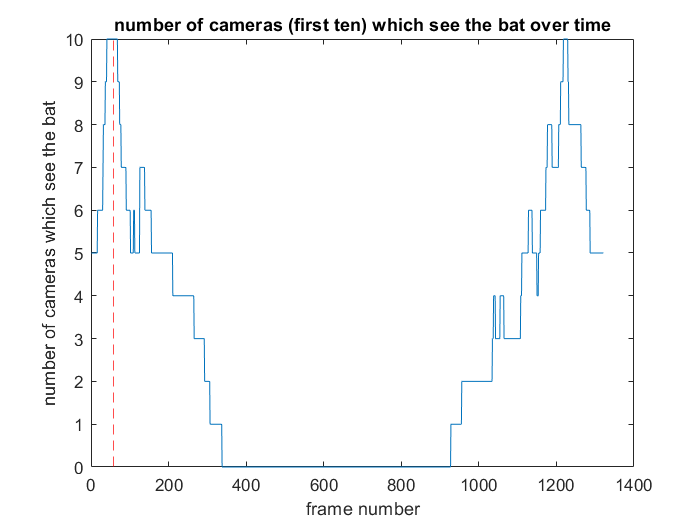

%plot the frame number, and how many cameras see the bat at that time
%get a one or zero in the index if the bat is present in the frame
batPresentBool = sign(batStoredFrame);

%sum these across the rows to get how many cameras see the bat in a
%particlular frame
numCamerasSee = sum(batPresentBool,2);

%plot this vs frame number
figure(2)
clf
hold off
plot(numCamerasSee);
xline(57,'r--')
xlabel("frame number")
ylabel("number of cameras which see the bat")
title("number of cameras (first ten) which see the bat over time")
%choose a frame from this sequence which sees the bat with all cameras and
%show the views
frameToShow = 57;

figure(3)
clf
hold on
%for each potential camera
for i = 1:length(camNames)
    
    %for each camera, load the corrosponding video
    camVid = VideoReader(fullfile(dataDirectory,camNames(i) + ".avi"));
    
    %if this camera saw the bat
    if batPresentBool(frameToShow,i) == 1
        
        %get the threshold image
        greyImg = rgb2gray(read(camVid,frameToShow));
        threshImg = imbinarize(greyImg,0.6);
        
        %plot the view of this camera
        subplot(2,5,i)
        imshow(threshImg);
        title("bat view " + camNames(i))
    end
end

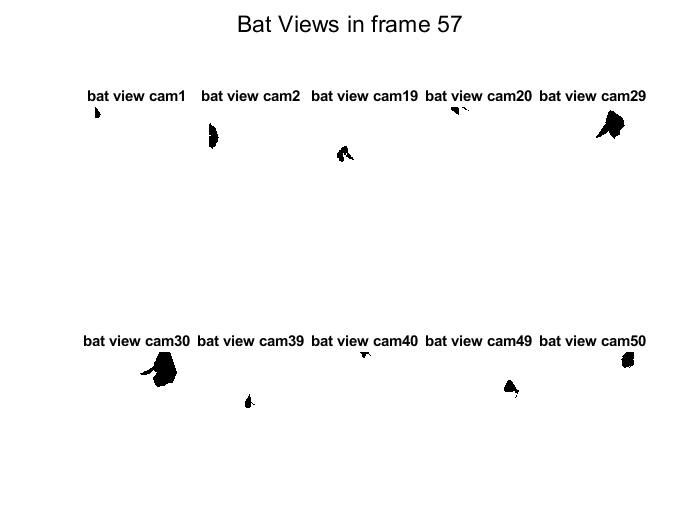

sgtitle("Bat Views in frame " + frameToShow) 
hold off

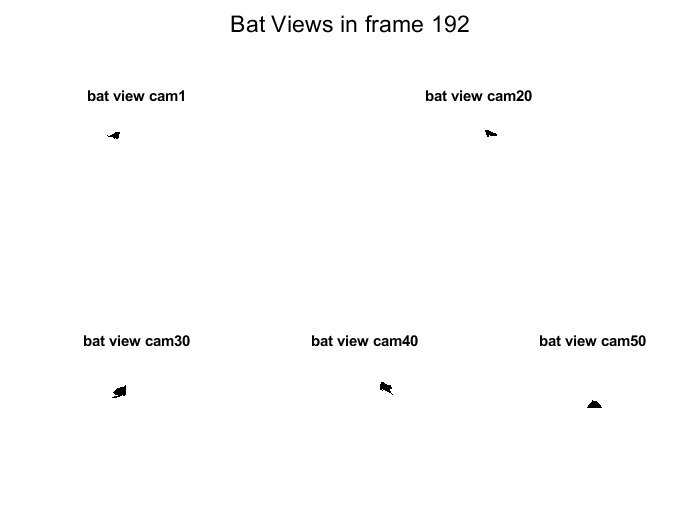

%choose a frame from this sequence which sees the bat from only 4-5 cameras
%and show the views
frameToShow = 192;

figure(4)
clf
hold on
%for each potential camera
for i = 1:length(camNames)
    
    %for each camera, load the corrosponding video
    camVid = VideoReader(fullfile(dataDirectory,camNames(i) + ".avi"));
    
    %if this camera saw the bat
    if batPresentBool(frameToShow,i) == 1
        
        %get the threshold image
        greyImg = rgb2gray(read(camVid,frameToShow));
        threshImg = imbinarize(greyImg,0.6);
        
        %plot the view of this camera
        subplot(2,5,i)
        imshow(threshImg);
        title("bat view " + camNames(i))
    end
end
sgtitle("Bat Views in frame " + frameToShow) 
hold off

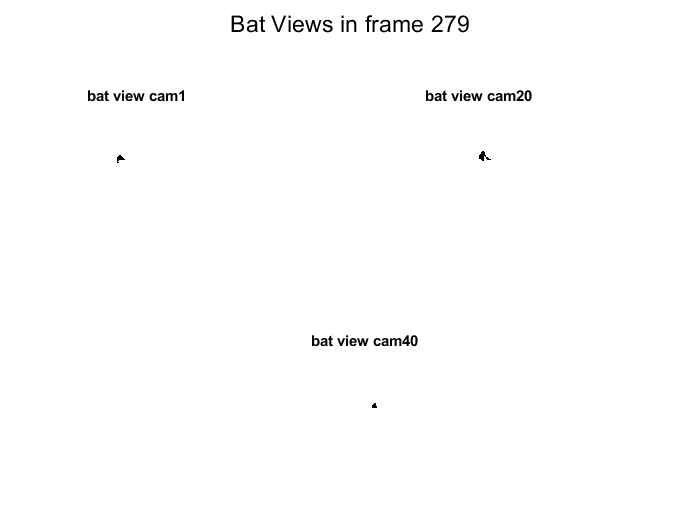


%now for only two cameras
frameToShow = 279;

figure(5)
clf
hold on
%for each potential camera
for i = 1:length(camNames)
    
    %for each camera, load the corrosponding video
    camVid = VideoReader(fullfile(dataDirectory,camNames(i) + ".avi"));
    
    %if this camera saw the bat
    if batPresentBool(frameToShow,i) == 1
        
        %get the threshold image
        greyImg = rgb2gray(read(camVid,frameToShow));
        threshImg = imbinarize(greyImg,0.6);
        
        %plot the view of this camera
        subplot(2,5,i)
        imshow(threshImg);
        title("bat view " + camNames(i))
    end
end
sgtitle("Bat Views in frame " + frameToShow) 
hold off

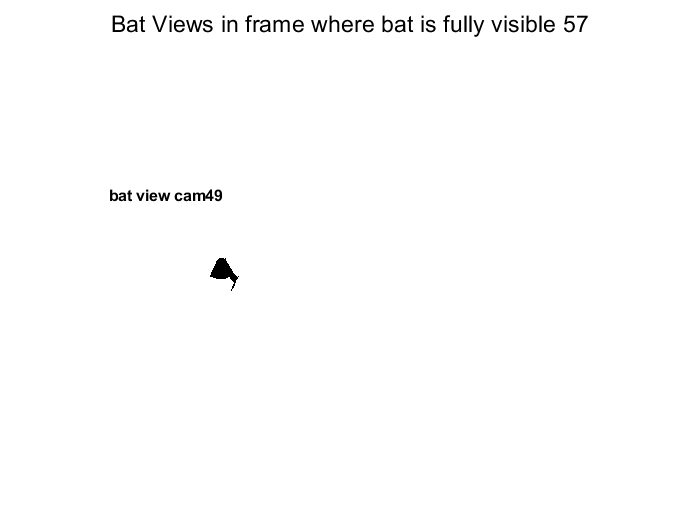

%additional method to only select the frames which see the bat, AND which
%have the full bat inside the bounds of the image

%display the cameras for which the bat is fully present in at the frame
%choose a frame from this sequence which sees the bat with all cameras and
%show the views
frameToShow = 57;

numFramesToShow = sum(batInsideFrame(frameToShow,:));

figure(3)
clf
hold on
%for each potential camera
for i = 1:length(camNames)
    
    %for each camera, load the corrosponding video
    camVid = VideoReader(fullfile(dataDirectory,camNames(i) + ".avi"));
    
    %if this camera saw the bat
    plottedFrames = 1;
    if (batPresentBool(frameToShow,i) == 1) && (batInsideFrame(frameToShow,i) == 1)
        
        %get the threshold image
        greyImg = rgb2gray(read(camVid,frameToShow));
        threshImg = imbinarize(greyImg,0.6);
        
        %plot the view of this camera
        subplot(1,numFramesToShow,plottedFrames)
        imshow(threshImg);
        title("bat view " + camNames(i))
        plottedFrames = plottedFrames + 1;
    end
end
sgtitle("Bat Views in frame where bat is fully visible " + frameToShow) 
hold off

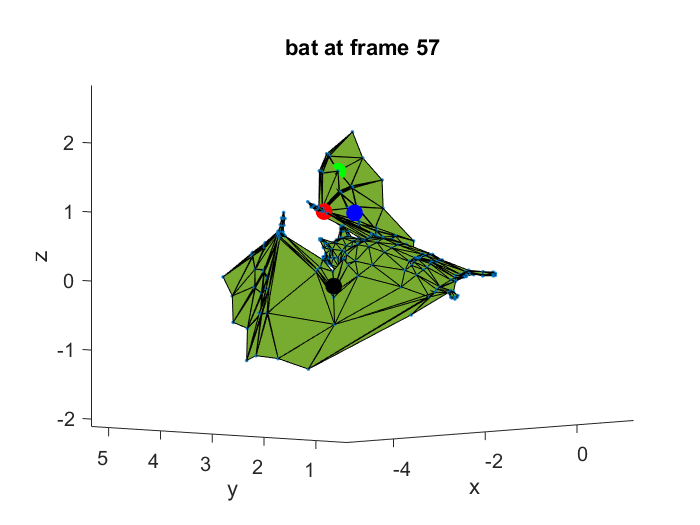

%test the way that the back-projection works
%get a camera, plot the view at a frame
%plot the bat somewhere near that view
%then plot a single point from a view and the same point in the image 
camNumToShow = 5;

%load the STL data
singleObjData = readObj(fullfile(directoryInfoMesh(3).folder,directoryInfoMesh(3).name));

%plot the stl data for the frame 57
figure(6)
clf
hold on
%plot the bat points
objVerticiesRedone = [singleObjData.v(:,1),-1*singleObjData.v(:,3),singleObjData.v(:,2)];
%objVerticiesRedone = [singleObjData.v(:,1),singleObjData.v(:,2),singleObjData.v(:,3)];
scatter3(objVerticiesRedone(:,1),objVerticiesRedone(:,2),objVerticiesRedone(:,3),'.');
set(gca,'fontsize',12);

%display the obj file
patch('Faces',singleObjData.f.v,'Vertices',objVerticiesRedone,'FaceColor',[0.4660 0.6740 0.1880])
axis equal
rotate3d on

%plot a single point, then some other points for visualization
singlePtIndex = 180;
scatter3(objVerticiesRedone(singlePtIndex,1),objVerticiesRedone(singlePtIndex,2),objVerticiesRedone(singlePtIndex,3),100,"go",'filled');

singlePtIndex = 150;
scatter3(objVerticiesRedone(singlePtIndex,1),objVerticiesRedone(singlePtIndex,2),objVerticiesRedone(singlePtIndex,3),100,"ro",'filled');

scatter3(objVerticiesRedone(singlePtIndex,1) + 0.1,objVerticiesRedone(singlePtIndex,2) - 0.5,objVerticiesRedone(singlePtIndex,3),100,"bo",'filled');

scatter3(-3.5,2,0,100,"ko",'filled');

view([-48.47 3.93])
title("bat at frame 57")
xlabel('x')
ylabel('y')
zlabel('z')

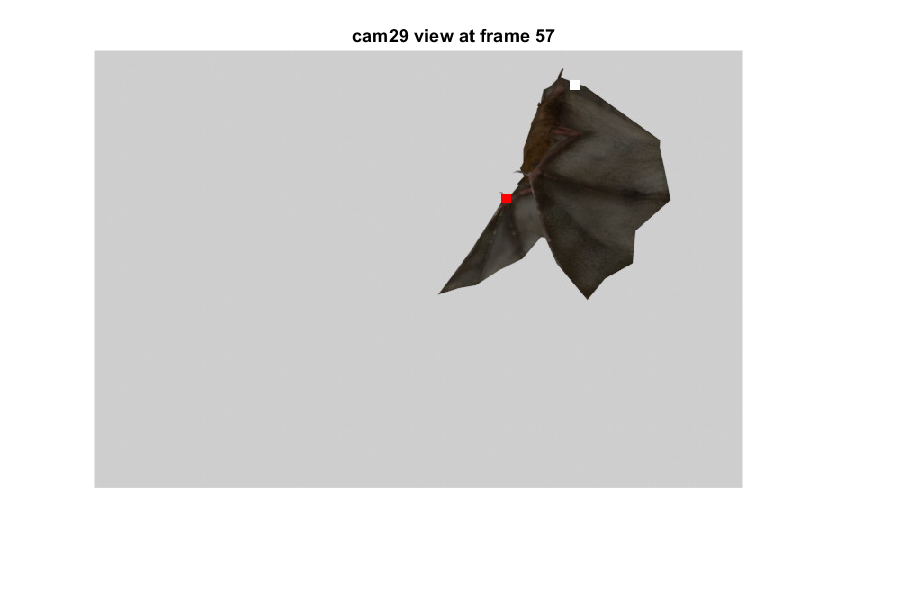

%save the single point for math
singlePt = [objVerticiesRedone(singlePtIndex,1);objVerticiesRedone(singlePtIndex,2);objVerticiesRedone(singlePtIndex,3);1];
singlePt1 = [-3.5,2,0,1]';

%get the projected point for this camera
%Pmat = [296.1358337402344 -219.66885375976562 -715.5761108398438 6701.06884765625; 567.5582275390625 406.45916748046875 -12.146903038024902 1554.8873291015625; 0.8289129734039307 -0.5592568516731262 0.011630085296928883 13.810522079467773];
Pmat = squeeze(camCombinedMat(camNumToShow,:,:));
projPoint1 = Pmat*singlePt;
projPoint2Scaled = projPoint1./projPoint1(3);


projPoint2 = Pmat*singlePt1;
projPoint3Scaled = projPoint2./projPoint2(3);

%now get the frame for a camera 
camVid = VideoReader(fullfile(dataDirectory,camNames(camNumToShow) + ".avi"));

%get the threshold image
% greyImg = rgb2gray(read(camVid,57));
% threshImg = imbinarize(greyImg,0.6);

nonThreshedView = read(camVid,57);
square = zeros(11,11,3);
square(:,:,1) = 255*ones([11 11]);
nonThreshedView(round(projPoint2Scaled(2)) - 5:round(projPoint2Scaled(2)) + 5,round(projPoint2Scaled(1)) - 5:round(projPoint2Scaled(1)) + 5,:) = square;

square(:,:,2) = 255*ones([11 11]);
square(:,:,3) = 255*ones([11 11]);
nonThreshedView(round(projPoint3Scaled(2)) - 5:round(projPoint3Scaled(2)) + 5,round(projPoint3Scaled(1)) - 5:round(projPoint3Scaled(1)) + 5,:) = square;

%plot the view of this camera
figure(7)
clf
hold on
axis on
imshow(nonThreshedView);
%scatter(round(projPoint2Scaled(2)),round(projPoint2Scaled(1)),"r*")
title(camNames(camNumToShow) + " view at frame 57")

%plot(projPoint2Scaled(1),projPoint2Scaled(2),"r");

For each timestep, for each frame with a bat, cast the rays such that we get the starting and ending points for the camera casting rays through the bat at that timestep. Store these starting and ending points

%for now, we just do this for one timestep, but we can do for every
%timestep if we want
f = 52;

%load the STL data
singleObjData = readObj(fullfile(directoryInfoMesh(3).folder,directoryInfoMesh(3).name));

%get the verticies
objVerticiesRedone = [singleObjData.v(:,1),-1*singleObjData.v(:,3),singleObjData.v(:,2)];

%find the maximum and minimum points of the bat here
bottLeftCorner = min(objVerticiesRedone);
topRightCorner = max(objVerticiesRedone);

%add a buffer of 0.1
bottLeftCorner = bottLeftCorner - [0.1 0.1 0.1];
topRightCorner = topRightCorner + [0.1 0.1 0.1];

%around this center point, create a voxel array which defines the cube
%volume where we check pixels
%set the array size to be 150 by 150 by 150
numSpacing = 50;
voxX = linspace(bottLeftCorner(1),topRightCorner(1),numSpacing);
voxY = linspace(bottLeftCorner(2),topRightCorner(2),numSpacing);
voxZ = linspace(bottLeftCorner(3),topRightCorner(3),numSpacing);

%get the voxel mesh
[voxMeshX, voxMeshY, voxMeshZ] = ndgrid(voxX,voxY,voxZ);

%create the meshgrid of position values we need to check
%convert this to a list of positions
voxPositions = [voxMeshX(:),voxMeshY(:),voxMeshZ(:)];

%create the array which holds the final positions
finalPositionOverlapVal = zeros([size(voxPositions,1),1]);

%for testing: extra matrix of just the cameras that fully see the bat
fullCams = [3,5,7,9];
%fullCams = [1,4,8];

%for each camera
for k = 1:length(fullCams)
    i = fullCams(k);
    %if, in this frame there is a blob
    if batStoredFrame(f,i) ~=0
        %get the image
        camVid = VideoReader(fullfile(dataDirectory,camNames(i) + ".avi"));
        rawFrame = read(camVid,f);
        greyImg = rgb2gray(rawFrame);
        threshImg = imbinarize(greyImg,0.6);
        
        %for each voxel position
        for p = 1:size(voxPositions,1)
            %get the voxel position, and use matrix math to compute the
            %camera space voxel projection, access the camera matrix here
            camSpaceVoxProjection = squeeze(camCombinedMat(i,:,:))*[voxPositions(p,:),1]';
            camSpaceVoxProjection = camSpaceVoxProjection./camSpaceVoxProjection(3);
            
            %get the indices of the point
            imgCoordx = round(camSpaceVoxProjection(2));
            imgCoordy = round(camSpaceVoxProjection(1));
            
            %check if the index is even inside the image coordinates
            if (imgCoordx > 0 && imgCoordx <= 486) && (imgCoordy > 0 && imgCoordy <= 720)
                %if this position has a white pixel, then add one to this
                %position value corrosponding in the list of positions
               
                if threshImg(imgCoordx,imgCoordy) == 0
                    %add one to the position
                   
                    finalPositionOverlapVal(p) = finalPositionOverlapVal(p) + 1; 
                end
            end
%             else 
%                 %remove this value from this list of positions
%                 %and final overlap values
%                 voxPositions(p,:) = [];
%                 finalPositionOverlapVal(p,:) = [];
%             end
        end
    end
end

Keep only the voxels with the strongest overlap here, this corrosponds to the voxel shape of the bat at a timestep

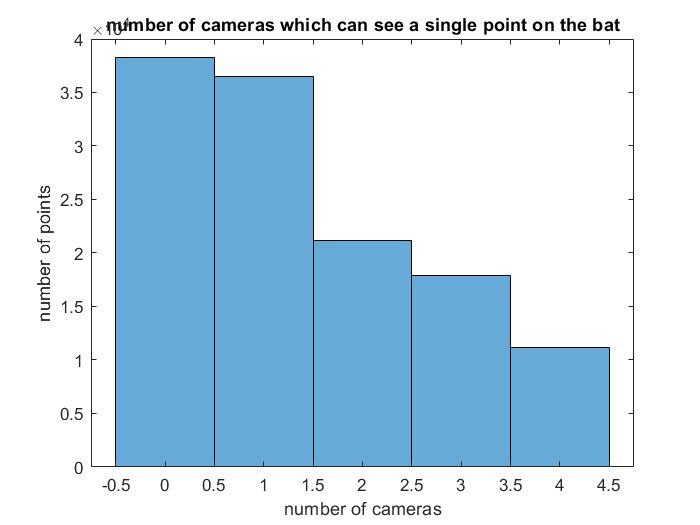

%look in the 3d matrix for the timestep, and keep only the voxels which
%have the HIGHEST value (or value less than the threshold

%first get the histogram
figure(8)
clf
histogram(finalPositionOverlapVal);
xlabel("number of cameras")
ylabel("number of points")
title("number of cameras which can see a single point on the bat")

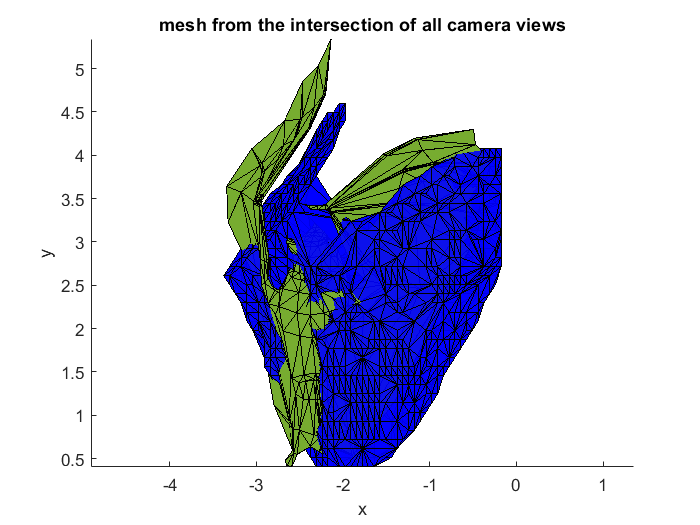

%set the threshold value here
thresh  = 4;

%then get the final positions
finalPositionOverlapVal1 = finalPositionOverlapVal;
finalPositionOverlapVal1(finalPositionOverlapVal1 < thresh) = 0;

%plot the voxels/point cloud
%get the indices
plotIndices = find(finalPositionOverlapVal1);
plotDataFinal = voxPositions(plotIndices,:);

%plot a scatter plot, and an isosurface
%isosurface(plotDataFinal(:,1),plotDataFinal(:,2),plotDataFinal(:,3));
figure(9)
clf
hold on
%scatter3(plotDataFinal(:,1),plotDataFinal(:,2),plotDataFinal(:,3),'r.');
% rotate3d on
% axis equal
k = boundary(plotDataFinal);
hold on
trisurf(k,plotDataFinal(:,1),plotDataFinal(:,2),plotDataFinal(:,3),'Facecolor','b','Facealpha',0.9)
patch('Faces',singleObjData.f.v,'Vertices',objVerticiesRedone,'FaceColor',[0.4660 0.6740 0.1880])
xlabel('x')
ylabel('y')
zlabel('z')
title("mesh from the intersection of all camera views")
axis equal


% figure(10)
% clf
% %try to plot the voxel array
% %first convert the list of positions to a voxel array
% voxArr = zeros([numSpacing numSpacing numSpacing]);
% 
% %for each position in the final positions, divide by the spacing to get the
% %position in the voxel array, set this position to one and keep the rest as
% %zero
% for i = 1:size(plotDataFinal,1)
%     %get the point in the correct coords, add one to all the indices here
%     %(i think)
%     pointToFillx = plotDataFinal(i,1);
% end

Finish by converting the voxelized body into a mesh